%%wind calculations
%wind density at 31km
rho = 0.015791

rho = 0.0158

%balloon volume
vol_f = 18.8e6;
vol_m = vol_f * 0.0283168

vol_m = 5.3236e+05


wind_vel = 25.5

wind_vel = 25.5000

%balloon radius in m, estimated as sphere
radius_m = nthroot((vol_m * 3 / 4 / pi),3)

radius_m = 50.2772

%https://blogs.nasa.gov/superpressureballoon/2016/04/04/nasas-super-pressure-balloon-by-the-numbers/
surface_area = 69*1145.5

surface_area = 7.9040e+04


wind_force = rho * wind_vel^2 * surface_area / 2

wind_force = 4.0579e+05


payload_mass = 2500;
balloon_mass = 2000;

Cd = 0.47;

accel_balloon = Cd*wind_force/balloon_mass

accel_balloon = 95.3613


length_tot = 35+60

length_tot = 95


alpha_bal = accel_balloon/length_tot

alpha_bal = 1.0038


s = tf('s');
Ds = 4.62*(s^2 + 0.21*s + 0.0225)/(s^2 + 0.016*s + 4e-4)

Ds =
 
  4.62 s^2 + 0.9702 s + 0.104
  ---------------------------
    s^2 + 0.016 s + 0.0004
 
Continuous-time transfer function.



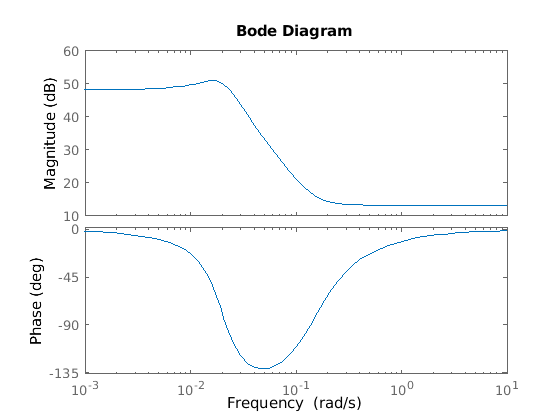


bode(Ds)

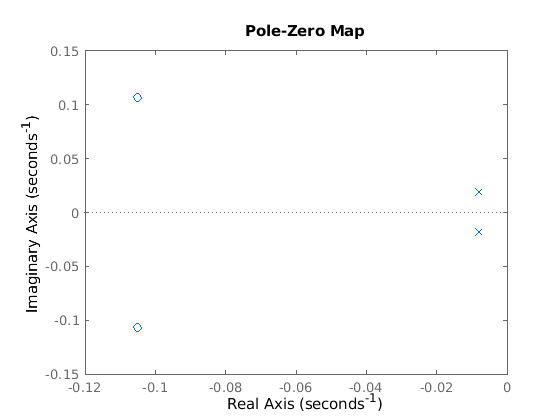

pzmap(Ds)


dsp.ColoredNoise('Color','pink')

ans =   dsp.ColoredNoise with properties:

              Color: 'pink'
    SamplesPerFrame: 1024
        NumChannels: 1
      BoundedOutput: false
     OutputDataType: 'double'
       RandomStream: 'Global stream'
